clear;

mnist=importdata("mnist.mat");
sample=60000;
x=double(mnist.trainX(1:sample,:));
%I saved my k=20 Nits=30 data so I could go back and forth and skip the
%caluation or section to do review
%z=importdata("z.mat");
%c=importdata("c.mat");
%jclust=importdata("jclust.mat");
k=5;
runs=10;
maxits=17;

z=zeros(runs,k,784);
jclust=zeros(runs,1);
c=zeros(runs,sample);

for it= 1:runs
    [c(it,:), z(it,1:k,1:784) ,jclust(it,1:maxits)] = kmeans(x,k,maxits);
end

Kmeans
Kmeans
Kmeans
Kmeans
Kmeans
Kmeans
Kmeans
Kmeans
Kmeans
Kmeans


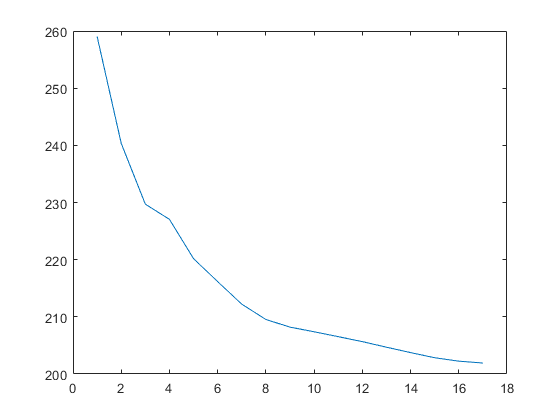

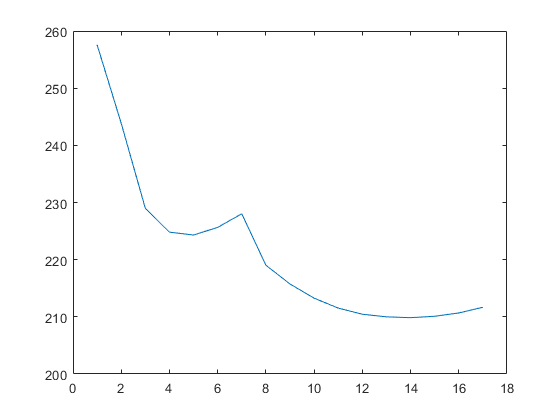

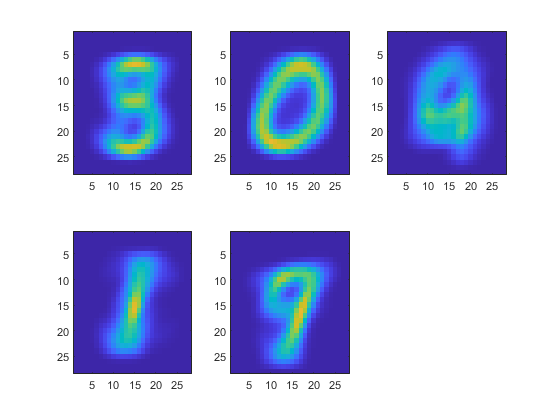

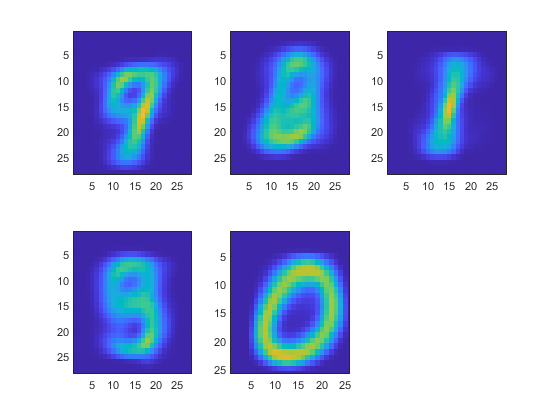

%get min and max runs by comparing the finishing positions
[minval,minind]=min(jclust(:,maxits));
[maxval,maxind]=max(jclust(:,maxits));


figure(1);
plot(1:maxits,jclust(minind,1:maxits));
jclust(minind,maxits);
figure(2);

plot(1:maxits,jclust(maxind,1:maxits));
jclust(maxind,maxits);
figure(3);
showz(z(minind,1:k,:),k);
figure(4);
showz(z(maxind,1:k,:),k);

%for

print("report generated");

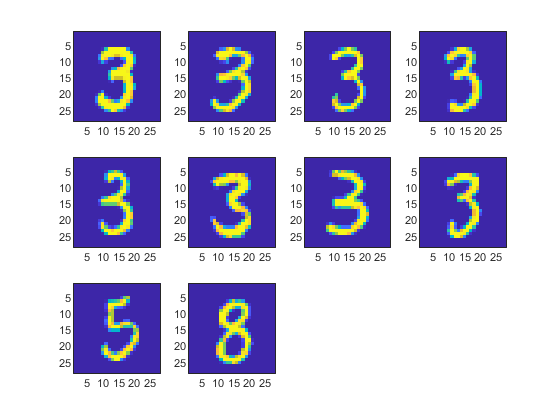

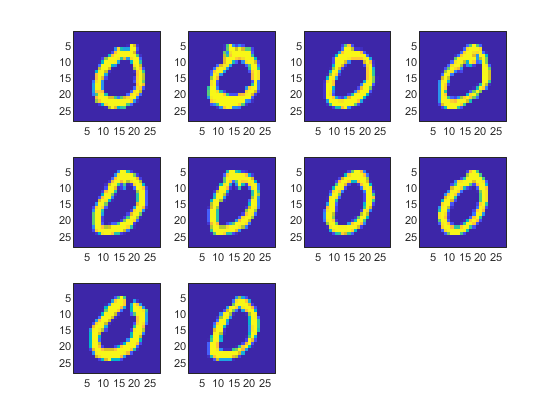

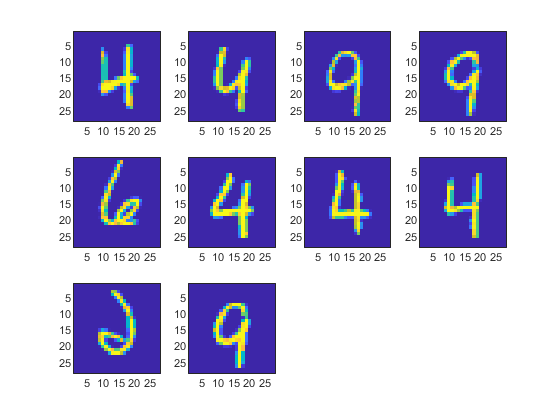

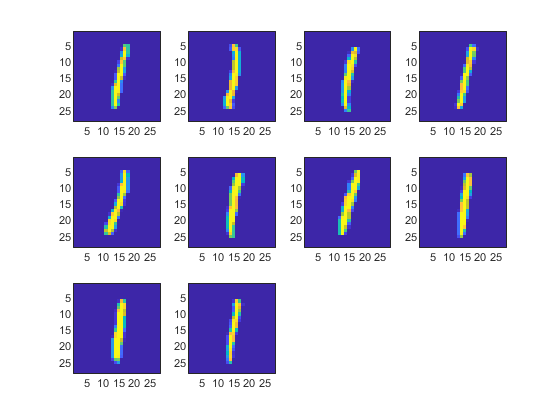

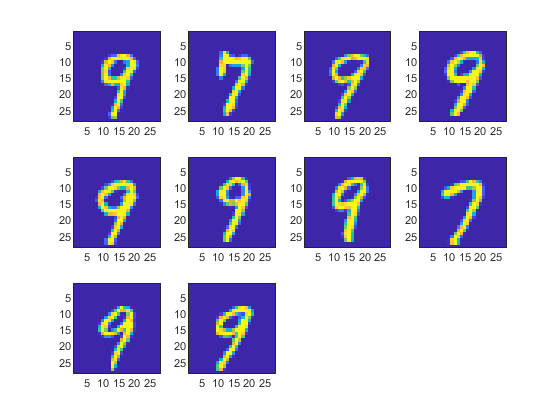

%get ten closest
[minval,minind]=min(jclust(:,maxits));
for it1=1:k
    %find how far away each item is
   for it2=1:6000
       temp(1:784)=z(minind,it1,1:784);
       xz=x(it2,1:784)-temp;
        j(it2)=norm(xz);
   end
   %grab the ten closest
   %[vals,indecies]=sort()
   for it2=1:10
        [val,indx]=min(j);
        tenlow(it1,it2,1:784)=x(indx,1:784);
        j(indx)=max(j);%jank code so i can find the next lowest value
   end
   figure(it1+5);
   showz(tenlow(it1,1:10,1:784),10);
end

function showz(zsetin,numin)
    gridw=round(sqrt(numin));
    for a=1:numin
      zim = reshape(zsetin(1,a,1:784), 28, 28);
      subplot(gridw,gridw+1,a);
      image(zim');
    end
end
